# **FDS 2024: Field and service robotics**

## `Homework 3 Question 4`

## Andrea Morghen

`Question 5`

Let's import and define some usefull parameter

clc
clear all

load("ws_homework_3_2024.mat");
m=1.5;
g=9.81;
Ib= diag([1.2416 1.2416 2*1.2416]);
Ts=1*10^-3;
e3=[0 0 1]';
time = attitude.time;
s=tf('s');

These are the parameter for the estimator. The parameter r can be chosen so that the order of the estimator can be changed

C0=10; 
K0=C0;
r=20; 

`Estimator `

q=zeros(6,length(time));
ext_wrench=zeros(6,length(time));
gamma=zeros(6,length(time),r); 
K=zeros(r,1)

K =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


p=1; % auxiliary variable

G=K0^r/(s+C0)^r

G =
 
                                                                                                                                             1e20
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^20 + 200 s^19 + 19000 s^18 + 1.14e06 s^17 + 4.845e07 s^16 + 1.55e09 s^15 + 3.876e10 s^14 + 7.752e11 s^13 + 1.26e13 s^12 + 1.68e14 s^11 + 1.848e15 s^10 + 1.68e16 s^9 + 1.26e17 s^8 + 7.752e17 s^7 + 3.876e18 s^6 + 1.55e19 s^5 + 4.845e19 s^4 + 1.14e20 s^3 + 1.9e20 s^2 + 2e20 s + 1e20
 
Continuous-time transfer function.


c=cell2mat(G.Denominator) % convert the type 

c = 1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0078    0.0388    0.1550    0.4845    1.1400    1.9000    2.0000    1.0000


c=c(2:end) %we cut off the first term since it is alway 1

c = 1.0e+20 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0078    0.0388    0.1550    0.4845    1.1400    1.9000    2.0000    1.0000



for i=1:r
K(i)=c(i)/p;
p=p*K(i); %we choose the K elements so that prod(i=j+1 to r) K_i = c_j
end

K=flip(K)

K =     0.5000
    1.0526
    1.6667
    2.3529
    3.1250
    4.0000
    5.0000
    6.1538
    7.5000
    9.0909




for k=1:length(time)-1
    % extract and compute the variable needed for the estimation
    RPY = attitude.signals.values(k,:);
    w = attitude_vel.signals.values(k,:);
        
    Q=[1 0 -sin(RPY(2));
        0 cos(RPY(1)) cos(RPY(2))*sin(RPY(1))
        0 -sin(RPY(1)) cos(RPY(1))*cos(RPY(2))];
    
    Q_dot=[0 0 -cos(RPY(2))*w(2);
           0 -sin(RPY(1))*w(1) -sin(RPY(2))*sin(RPY(1))*w(2)+cos(RPY(2))*cos(RPY(1))*w(1);
           0 -cos(RPY(1))*w(1) -sin(RPY(2))*cos(RPY(1))*w(2)-cos(RPY(2))*sin(RPY(1))*w(1)];
    
    S=skew(Q*attitude_vel.signals.values(k,:)');
    
    C=Q'*S*Ib*Q+Q'*Ib*Q_dot;
    
    M=Q'*Ib*Q;
    
    q(:,k+1)=[m*eye(3) zeros(3,3); zeros(3,3) M]*[linear_vel.signals.values(k+1,:)' ; attitude_vel.signals.values(k+1,:)']  ;
    
    Rb=[cos(RPY(2))*cos(RPY(3)) sin(RPY(1))*sin(RPY(2))*cos(RPY(3))-cos(RPY(1))*sin(RPY(3)) cos(RPY(1))*sin(RPY(2))*cos(RPY(3))+sin(RPY(1))*sin(RPY(3));
        cos(RPY(2))*sin(RPY(3)) sin(RPY(1))*sin(RPY(2))*sin(RPY(3))+cos(RPY(1))*cos(RPY(3)) cos(RPY(1))*sin(RPY(2))*sin(RPY(3))-sin(RPY(1))*cos(RPY(3));
        -sin(RPY(2)) sin(RPY(1))*cos(RPY(2)) cos(RPY(1))*cos(RPY(2))];

    % estimation 
    gamma(:,k+1,1)=gamma(:,k,1)+K(1)*((q(:,k+1)-q(:,k))-Ts*[m*g*e3-thrust.signals.values(k)*Rb*e3;C'*attitude_vel.signals.values(k,:)'+Q'*tau.signals.values(k,:)']-Ts*ext_wrench(:,k));
    if r>=2
        for i=2:r
           gamma(:,k+1,i)=gamma(:,k,i)+Ts*K(i)*(-ext_wrench(:,k)+gamma(:,k,i-1) );
        end
    end
   ext_wrench(:,k+1)=gamma(:,k+1,r); %extract the last estimation level
end


`Plotting the results`

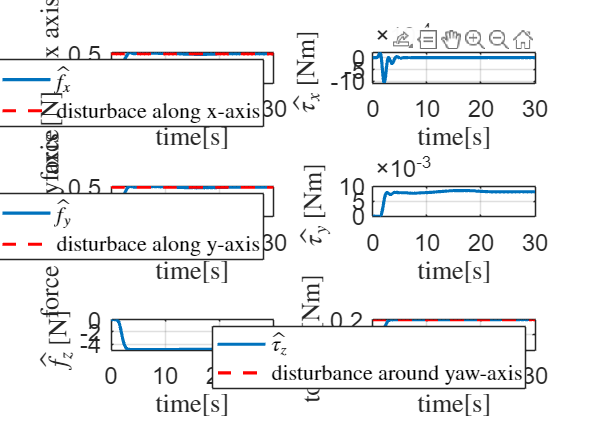

fext_x=0.5;
fext_y=0.5;
tauext_yaw=0.2;

figure()
subplot(3,2,1)
plot(time,ext_wrench(1,:),'lineWidth',2)
ylabel('force along x axis [N]','Interpreter','latex')
xlabel('time[s]','Interpreter','latex')
grid("on");
hold on
plot(time,fext_x.*ones(length(time),1),'--r','LineWidth',2)
hold on
legend('$\hat{f_x}$','disturbace along x-axis' ,'Interpreter', 'latex')
set(gca,'Fontsize',15)

subplot(3,2,3)
plot(time,ext_wrench(2,:),'lineWidth',2)
ylabel(' force along y axis [N] ','Interpreter','latex')
xlabel('time[s]','Interpreter','latex')
grid("on");
hold on
plot(time,fext_y.*ones(length(time),1),'--r','LineWidth',2)
hold on
legend('$\hat{f_y}$','disturbace along y-axis' ,'Interpreter', 'latex')
set(gca,'Fontsize',15)

subplot(3,2,5)
plot(time,ext_wrench(3,:),'lineWidth',2)
ylabel('$\hat{f_z}$ [N] ','Interpreter','latex')
xlabel('time[s]','Interpreter','latex')
grid("on");
set(gca,'Fontsize',15)


subplot(3,2,2)
plot(time,ext_wrench(4,:),'lineWidth',2)
ylabel('$\hat{\tau_x}$ [Nm] ','Interpreter','latex')
xlabel('time[s]','Interpreter','latex')
grid("on");
hold on
set(gca,'Fontsize',15)

subplot(3,2,4)
plot(time,ext_wrench(5,:),'lineWidth',2)
ylabel('$\hat{\tau_y}$ [Nm] ','Interpreter','latex')
xlabel('time[s]','Interpreter','latex')
grid("on");
hold on
set(gca,'Fontsize',15)

subplot(3,2,6)
plot(time,ext_wrench(6,:),'lineWidth',2)
ylabel('torque [Nm] ','Interpreter','latex')
xlabel('time[s]','Interpreter','latex')
grid("on");
hold on
plot(time,tauext_yaw.*ones(length(time),1),'--r','LineWidth',2)
hold on
legend('$\hat{\tau_z}$','disturbance around yaw-axis','Interpreter', 'latex')
set(gca,'Fontsize',15)

`compute real mass`

u_tb=thrust.signals.values(end)*Rb*e3;
mass_r_z_1=u_tb(3)/g; % not using disturbance but the steady-state equation

m_tilde= -ext_wrench(3,end)/g;

mass_r_z_2=-m_tilde+m; % computation using the z-disturbance 